# HW_9

## plot the shear diagram

shear = [7.62e4, -23800, -23800, -27950, -27950, 22050, 22050 -2950, 11250, -13750, -13750]

shear =        76200      -23800      -23800      -27950      -27950       22050       22050       -2950       11250      -13750      -13750


locations = [1:3,3:4,4:6,6:8]

locations =      1     2     3     3     4     4     5     6     6     7     8


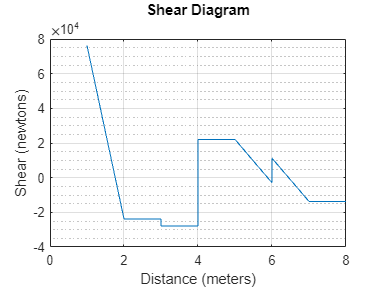


figure1 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);
axes1 = axes('Parent',figure1); hold(axes1,'on');
plot(locations,shear);
ylabel('Shear (newtons)'); xlabel('Distance (meters)');
title({'Shear Diagram',''}); box(axes1,'on'); hold(axes1,'off');
set(axes1,'XGrid','on','YGrid','on','YMinorGrid','on');

## compute the load distribution

syms x
pointLoad4 = 50e3*dirac(x-3)

$$pointLoad4 = 50000\,\delta (x-3)$$

distributedLoad12 = -100e3*(heaviside(x) - heaviside(x-1))

$$distributedLoad12 = 100000\,\mathrm{heaviside}\left(x-1\right)-100000\,\mathrm{heaviside}\left(x\right)$$

distributedLoad57 = -50e3*(heaviside(x-4) - heaviside(x-6))

$$distributedLoad57 = 50000\,\mathrm{heaviside}\left(x-6\right)-50000\,\mathrm{heaviside}\left(x-4\right)$$

externalAppliedloads = pointLoad4 + distributedLoad12 + distributedLoad57

$$externalAppliedloads = 50000\,\delta (x-3)+100000\,\mathrm{heaviside}\left(x-1\right)-50000\,\mathrm{heaviside}\left(x-4\right)+50000\,\mathrm{heaviside}\left(x-6\right)-100000\,\mathrm{heaviside}\left(x\right)$$

reactionLoad1 = 7.62e3*dirac(x)

$$reactionLoad1 = 7620\,\delta (x)$$

reactionLoad3 = -4.15e3*dirac(x-3)

$$reactionLoad3 = -4150\,\delta (x-3)$$

reactionLoad6 = 1.42e4*dirac(x-6)

$$reactionLoad6 = 14200\,\delta (x-6)$$

reactionLoad8 = 1.37e4*dirac(x-8)

$$reactionLoad8 = 13700\,\delta (x-8)$$

reactionLoads = reactionLoad1 + reactionLoad3 + reactionLoad6 + reactionLoad8

$$reactionLoads = 14200\,\delta (x-6)-4150\,\delta (x-3)+13700\,\delta (x-8)+7620\,\delta (x)$$


totalLoad = externalAppliedloads + reactionLoads

$$totalLoad = 45850\,\delta (x-3)+14200\,\delta (x-6)+13700\,\delta (x-8)+100000\,\mathrm{heaviside}\left(x-1\right)-50000\,\mathrm{heaviside}\left(x-4\right)+50000\,\mathrm{heaviside}\left(x-6\right)+7620\,\delta (x)-100000\,\mathrm{heaviside}\left(x\right)$$


reactionMoment8 = -8.6e3*dirac(x-8)

$$reactionMoment8 = -8600\,\delta (x-8)$$


% y1 = int(totalLoad)
% fplot(y1)

## plot the shear diagram with a function

syms x
y = piecewise(...
    x==0, 0, ...
    (x > 0) & (x < 1), 7.62e4-100e3*x, ...
    (x >= 1) & (x < 2), -23800, ...
    (x >= 2) & (x < 3), -27950, ...
    (x >= 3) & (x < 4), 22050, ...
    (x >= 4) & (x < 5), 22050-25e3*(x-4), ...
    (x >= 5) & (x < 6), 11250-25e3*(x-5), ...
    (x >= 6) & (x < 7), -13750, ...
    x==7, 0 )

$$y = \left\{ \begin{array}{cl} 0 & \text{ if }x=0\\ 76200-100000\,x & \text{ if }x\in \left(0,1\right)\\ -23800 & \text{ if }x\in \left[1,2\right)\\ -27950 & \text{ if }x\in \left[2,3\right)\\ 22050 & \text{ if }x\in \left[3,4\right)\\ 122050-25000\,x & \text{ if }x\in \left[4,5\right)\\ 136250-25000\,x & \text{ if }x\in \left[5,6\right)\\ -13750 & \text{ if }x\in \left[6,7\right)\\ 0 & \text{ if }x=7 \end{array}\right.$$

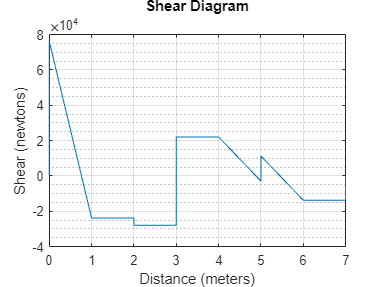

figure2 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);
axes2 = axes('Parent',figure2); hold(axes2,'on');
fplot(y);
xlim([0,7]); ylim([-40000,8e4]);
ylabel('Shear (newtons)'); xlabel('Distance (meters)');
title({'Shear Diagram',''}); box(axes2,'on'); hold(axes2,'off');
set(axes2,'XGrid','on','YGrid','on','YMinorGrid','on');

## plot moment diagram

Y = int(y)

$$Y = \left\{ \begin{array}{cl} 0 & \text{ if }x=0\\ -200\,x\,\left(250\,x-381\right) & \text{ if }x\in \left(0,1\right)\\ -23800\,x & \text{ if }x\in \left[1,2\right)\\ -27950\,x & \text{ if }x\in \left[2,3\right)\\ 22050\,x & \text{ if }x\in \left[3,4\right)\\ -50\,x\,\left(250\,x-2441\right) & \text{ if }x\in \left[4,5\right)\\ -1250\,x\,\left(10\,x-109\right) & \text{ if }x\in \left[5,6\right)\\ -13750\,x & \text{ if }x\in \left[6,7\right)\\ 0 & \text{ if }x=7 \end{array}\right.$$


Y1 = piecewise(...
    x == 0, 0,...
    0 < x & x < 1, -200*x*(250*x - 381),...
    1 <= x & x < 2, -23800*(x-1) + (-200*1*(250*1 - 381)),...
    2 <= x & x < 3, -27950*(x-2) + subs(-23800*(x-1) + (-200*1*(250*1 - 381)),2),...
    3 <= x & x < 4, 22050*(x-3) + subs(-27950*(x-2) + subs(-23800*(x-1) + (-200*1*(250*1 - 381)),2),3),...
    4 <= x & x < 5, -50*x*(250*x - 2441),...
    5 <= x & x < 6, -1250*x*(10*x - 109),...
    6 <= x & x < 7, -13750*x,...
    x == 7, 0);

Y2 =piecewise(...
    x == 0, 0,...
    0 < x & x < 1, -200*x*(250*x - 381),...
    1 <= x & x < 2, 50000 - 23800*x,...
    2 <= x & x < 3, 58300 - 27950*x,...
    3 <= x & x < 4, 22050*x - 91700,...
    4 <= x & x < 5, -50*(x-4)*(250*(x-4) - 2441) + subs(22050*x - 91700,4),...
    5 <= x & x < 6, -1250*(x-5)*(10*(x-5) - 109) + subs(-50*(x-4)*(250*(x-4) - 2441) + subs(22050*x - 91700,4),5),...
    6 <= x & x < 7, -13750*(x-6) + subs(-1250*(x-5)*(10*(x-5) - 109) + subs(-50*(x-4)*(250*(x-4) - 2441) + subs(22050*x - 91700,4),5),6),...
    x == 7, 0)

$$Y2 = \left\{ \begin{array}{cl} 0 & \text{ if }x=0\\ -200\,x\,\left(250\,x-381\right) & \text{ if }x\in \left(0,1\right)\\ 50000-23800\,x & \text{ if }x\in \left[1,2\right)\\ 58300-27950\,x & \text{ if }x\in \left[2,3\right)\\ 22050\,x-91700 & \text{ if }x\in \left[3,4\right)\\ -\left(50\,x-200\right)\,\left(250\,x-3441\right)-3500 & \text{ if }x\in \left[4,5\right)\\ 106050-\left(10\,x-159\right)\,\left(1250\,x-6250\right) & \text{ if }x\in \left[5,6\right)\\ 312300-13750\,x & \text{ if }x\in \left[6,7\right)\\ 0 & \text{ if }x=7 \end{array}\right.$$


Y3 =piecewise(...
    x == 0, 0,...
    0 < x & x < 1, -200*x*(250*x - 381),...
    1 <= x & x < 2, 50000 - 23800*x,...
    2 <= x & x < 3, 58300 - 27950*x,...
    3 <= x & x < 4, 22050*x - 91700,...
    4 <= x & x < 5, -50*x*(250*x - 2441) + subs(22050*x - 91700,4) - subs(-50*x*(250*x - 2441),4),...
    5 <= x & x < 6, -1250*x*(10*x - 109) + subs(-50*x*(250*x - 2441) + subs(22050*x - 91700,4) - subs(-50*x*(250*x - 2441),4),5) - subs(-1250*x*(10*x - 109),5),...
    6 <= x & x < 7, -13750*(x-6) +subs(-1250*x*(10*x - 109) + subs(-50*x*(250*x - 2441) + subs(22050*x - 91700,4) - subs(-50*x*(250*x - 2441),4),5) - subs(-1250*x*(10*x - 109),5),6),...
    x == 7, 0)

$$Y3 = \left\{ \begin{array}{cl} 0 & \text{ if }x=0\\ -200\,x\,\left(250\,x-381\right) & \text{ if }x\in \left(0,1\right)\\ 50000-23800\,x & \text{ if }x\in \left[1,2\right)\\ 58300-27950\,x & \text{ if }x\in \left[2,3\right)\\ 22050\,x-91700 & \text{ if }x\in \left[3,4\right)\\ -50\,x\,\left(250\,x-2441\right)-291700 & \text{ if }x\in \left[4,5\right)\\ -1250\,x\,\left(10\,x-109\right)-362700 & \text{ if }x\in \left[5,6\right)\\ 87300-13750\,x & \text{ if }x\in \left[6,7\right)\\ 0 & \text{ if }x=7 \end{array}\right.$$

Y4 = piecewise(x == 0, 0, 0 < x & x < 1, -200*x*(250*x - 381), 1 <= x & x < 2, 50000 - 23800*x, 2 <= x & x < 3, 58300 - 27950*x, 3 <= x & x < 4, 22050*x - 91700, 4 <= x & x < 5, - 50*x*(250*x - 2441) - 291700, 5 <= x & x < 6, - 1250*x*(10*x - 109) - 362700, 6 <= x & x < 7, 87300 - 13750*x, x == 7, 0) % simplified version

$$Y4 = \left\{ \begin{array}{cl} 0 & \text{ if }x=0\\ -200\,x\,\left(250\,x-381\right) & \text{ if }x\in \left(0,1\right)\\ 50000-23800\,x & \text{ if }x\in \left[1,2\right)\\ 58300-27950\,x & \text{ if }x\in \left[2,3\right)\\ 22050\,x-91700 & \text{ if }x\in \left[3,4\right)\\ -50\,x\,\left(250\,x-2441\right)-291700 & \text{ if }x\in \left[4,5\right)\\ -1250\,x\,\left(10\,x-109\right)-362700 & \text{ if }x\in \left[5,6\right)\\ 87300-13750\,x & \text{ if }x\in \left[6,7\right)\\ 0 & \text{ if }x=7 \end{array}\right.$$

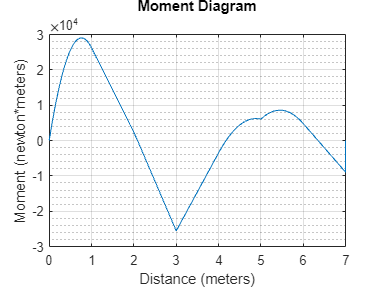


figure3 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1]);
axes3 = axes('Parent',figure3); hold(axes3,'on');
fplot(Y3);
xlim([0,7]);
ylabel('Moment (newton*meters)'); xlabel('Distance (meters)');
title({'Moment Diagram',''}); box(axes3,'on'); hold(axes3,'off');
set(axes3,'XGrid','on','YGrid','on','YMinorGrid','on');

## find the maxiumum moment

func = @(x)-(-200*x*(250*x - 381));
[location,max] = fminbnd(func,.6,.8) % bound from inspection

location = 0.7620

max = -2.9032e+04


location = solve(diff(-200*x*(250*x - 381)) == 0,x)

$$location = \frac{381}{500}$$

vpa(location)

$$ans = 0.762$$

max = subs(-200*x*(250*x - 381),x,location)

$$max = \frac{145161}{5}$$

vpa(max)

$$ans = 29032.2$$

## Maximum stress

sigma_max = (max*55e-3/2)/(1/12*36e-3*55e-3^3)

$$sigma\_max = \frac{942567231402280782189821952}{589262792690577875}$$

vpa(sigma_max,12)

$$ans = 1599570247.93$$

fprintf("%g",vpa(sigma_max,12))

1.59957e+09